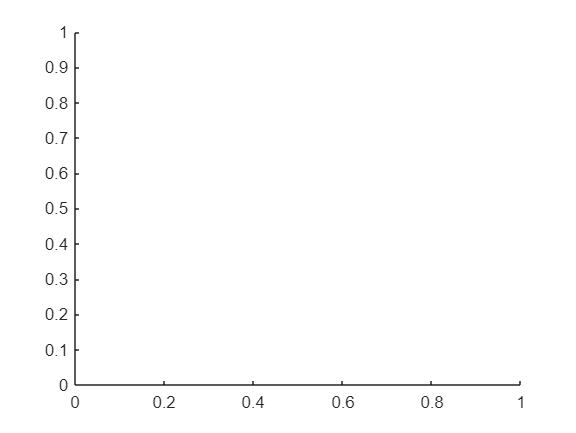


clear all
hold on

%lectura curva PWP201, es la que aparece en el artículo de Cubas
Ve= transpose(xlsread('PWP201.xlsx','u4:u29'));
Ie= transpose(xlsread('PWP201.xlsx','v4:v29'));
%Definición datos PWP201
Voc=16.7785;
Isc=1.0317;
Imp=0.9120;
Vmp=12.6490;
Ns=36;
T=45;
%constantes físicas
q=1.60218*10^(-19);
K=1.380649*10^(-23);
%Calculo Vth 
Vth=Ns*K*(T+273.15)/q;
%n en caso del método directo
%n=1.3;
%Obtención pendientes
Cs=0.11175;
Csh=34.49692;
Rs0=Cs*Voc/Isc;
Rsh0=Csh*Voc/Isc;
A=(Vmp+(Imp-Isc)*Rsh0)*log((Vmp+(Imp-Isc)*Rsh0)/(Voc-Isc*Rsh0));
B=Vmp-Rsh0*Imp;
%Rs en la solución de Cubas sin fijar n
Rs=((A-B)/(A+B))*(Vmp/Imp)+(B/(A+B))*(Voc/Imp)

Rs = 1.3329

%Rs en el caso del método directo
%syms Rs
%eqn=exp((Vmp+Imp*Rs-Voc)/(n*Vth))==(n*Vth*Vmp*(2*Imp-Isc))/((Vmp*Isc+Voc*(Imp-Isc))*(Vmp-Rs*Imp)-n*Vth*(Vmp*Isc-Voc*Imp));
%Rs=double(vpasolve(eqn,Rs));
%n en el caso de la solución de Cubas sin fijar n
n=(Vmp-Imp*Rs)*(Vmp+(Imp-Isc)*Rsh0)/(Vth*(Vmp-Imp*Rsh0))   ;
Rsh=(Vmp-Imp*Rs)*(Vmp-Rs*(Isc-Imp)-n*Vth)/((Vmp-Imp*Rs)*(Isc-Imp)-n*Vth*Imp);
Iph=Isc*(Rs+Rsh)/Rsh;
Io=((Rsh+Rs)*Isc-Voc)/(exp(Voc/(n*Vth))*Rsh);
for i=1:length(Ve)
    clear I    
    syms I
    eqn1=I==Iph-Io*(exp((Ve(i)+I*Rs)/(n*Vth))-1)-(Ve(i)+I*Rs)/Rsh;
    Ik=vpasolve(eqn1,I);
    Isol(i)=double(Ik);
end
%obtención RMSE
RMSE=rmse(Isol,Ie);

